# newton 2d optimization

% f: 2 scalars -> 1 scalar
% hessian: 2 scalars -> 2x2 matrix
% dfdx: 2 scalars -> 2x1 vector
% x_n+1 = x_n - inv(H(f))*dfdx(x_n)
% H(f) d = -dfdx(x_n) --> x_n+1 = x_n+d

function [xs,n,converged] = newton2d(x0,y0,hessian,dfdx,N,tol)
    converged = false;

    n = 1;

    xs = zeros(N+1,2);
    xs(1,:) = [x0 y0];

    % n = number of elements in array = index of last x in array
    % n-1 = number of completed iterations
    % n-1 = index of last computed x

    g0 = dfdx(x0,y0);
    if norm(g0)<tol
        error("at min point already");
    end

    while n-1<N
        H = hessian(xs(n,1),xs(n,2));

        %if(det(H)<1e-16)
        %    error("H = singular, det H = %d at step %d where (%d,%d)\n",det(H),n,xs(n,1),xs(n,2));
        %end

        g = dfdx(xs(n,1),xs(n,2));

        if det(H) < 1e-16 || norm(g) < tol*(1+norm(g0))
            converged = true;
            break;
        end

        xs(n+1,:) = xs(n,:) - (H\g)'; % x_n - H(f)(x_n)^(-1)*dfdx(x_n)
        
        n = n+1;

    end

    xs = xs(1:n,:);
end

## plot

function plot_function(ax,f,xmin,xmax,ymin,ymax)
    density = 100;
    xrange = xmax-xmin;
    yrange = ymax-ymin;

    [X,Y] = meshgrid(linspace(xmin,xmax,xrange*density),linspace(ymin,ymax,yrange*density));
    Z = f(X,Y);

    surf(ax,X,Y,Z,'EdgeColor','none');
    shading flat;
end

function plot_iteration(ax,f,xs)
    plot(ax,xs(1,1),xs(1,2),'.r','MarkerSize',9);
    
    n = length(xs);
    for i=2:n
        plot3(ax,[xs(i-1,1) xs(i,1)],[xs(i-1,2) xs(i,2)],[f(xs(i-1,1),xs(i-1,2)) f(xs(i,1),xs(i,2))],'-k','LineWidth',1);
        if i==n
            plot3(ax,xs(i,1),xs(i,2),f(xs(i,1),xs(i,2)),'.g','MarkerSize',9);
        else
            plot3(ax,xs(i,1),xs(i,2),f(xs(i,1),xs(i,2)),'.k','MarkerSize',9);
        end
    end
end

function plot_contours(ax,f,xmin,xmax,ymin,ymax)
    density = 10;
    xrange = xmax-xmin;
    yrange = ymax-ymin;

    [X,Y] = meshgrid(linspace(xmin,xmax,xrange*density),linspace(ymin,ymax,yrange*density));
    Z = f(X,Y);

    contourf(ax,X,Y,Z);
    colorbar(ax);
end

function plot_contour_descent(ax,xs)
    n = length(xs);
    plot(ax,xs(1,1),xs(1,2),'.r','MarkerSize',9);
    for i=2:n
        plot(ax,[xs(i-1,1) xs(i,1)],[xs(i-1,2) xs(i,2)],'-k','LineWidth',1);
        if(i==n)
            plot(ax,xs(i,1),xs(i,2),'.g','MarkerSize',9);
        else
            plot(ax,xs(i,1),xs(i,2),'.k','MarkerSize',9);
        end
    end
end

function plot_all(ax1,ax2,x0,y0,f,hessian,dfdx,N,tol,xmin0,xmax0,ymin0,ymax0)
    ratio = 0.6;

    [xs,n,converged] = newton2d(x0,y0,hessian,dfdx,N,tol);

    if n==1
        error("min already\n");
    end

    x = xs(:,1);
    y = xs(:,2);
    xmin = min(xmin0,min(x)-ratio*abs(min(x)));
    xmax = max(xmax0,max(x)+ratio*abs(max(x)));
    ymin = min(ymin0,min(y)-ratio*abs(min(y)));
    ymax = max(ymax0,max(y)+ratio*abs(max(y)));

    plot_function(ax1,f,xmin,xmax,ymin,ymax);
    plot_iteration(ax1,f,xs);

    plot_contours(ax2,f,xmin,xmax,ymin,ymax);
    plot_contour_descent(ax2,xs);

    if converged
        fprintf("Converged in %d steps\n",n);
    else
        fprintf("Not converged\n");
    end

    fprintf("(x,y) = (%d, %d)\n",x(end),y(end));
end

## variables

function a = f(x,y)
    a = x.^2+y.^2+exp(2.*x+y);
end

function d = dfdx(x,y)
    d = zeros(2,1);
    d(1) = 2.*x+2.*exp(2.*x+y);
    d(2) = 2.*y+exp(2.*x+y);
end

function h = hessian(x,y)
    h = [2+4.*exp(2.*x+y) 2.*exp(2.*x+y); 2.*exp(2.*x+y) exp(2.*x+y)+2];
end

N = 2;
tol = 2e-7;

## driver

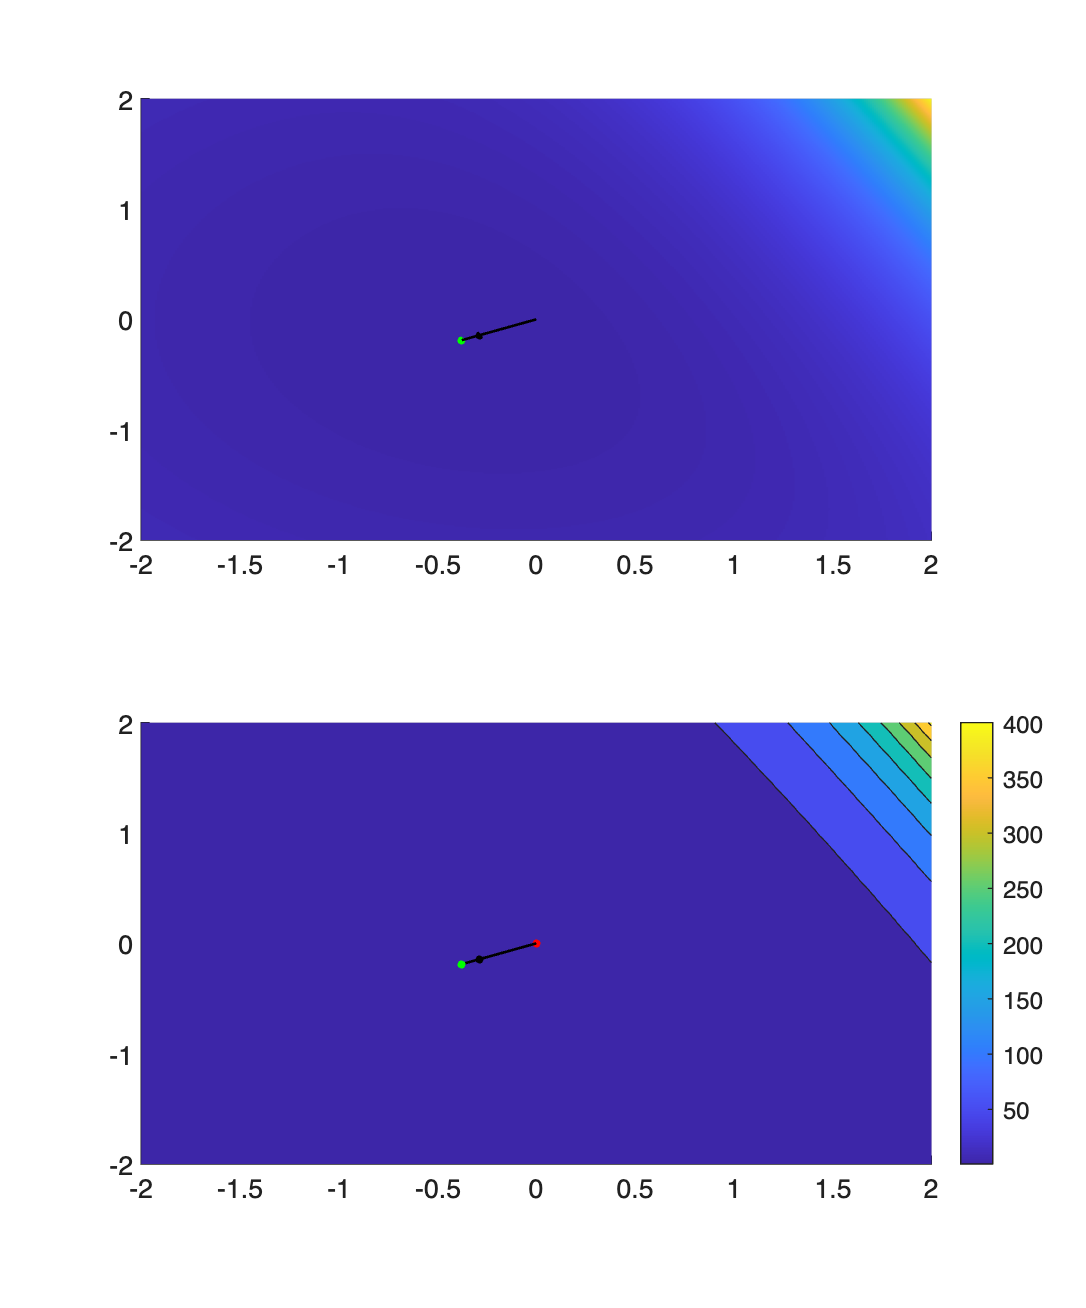

Not converged
(x,y) = (-3.773693e-01, -1.886846e-01)


h = figure;
h.Position(4) = h.Position(4)*2;

tiledlayout;
nexttile;
ax1 = gca;
nexttile;
ax2 = gca;

hold(ax1,'on');
grid(ax1,'on');
hold(ax2,'on');
grid(ax2,'on');

xmin0 = -2;
xmax0 = 2;
ymin0 = -2;
ymax0 = 2;

x0 = 0;
y0 = 0;
plot_all(ax1,ax2,x0,y0,@f,@hessian,@dfdx,N,tol,xmin0,xmax0,ymin0,ymax0);